%%Script to compute absolute velocity, x/y velocities and cell angle using
%%Difference of Gaussian tracking data from TrackMate
clc
clear all

%%Paste script into working directory containing microscopy files and
%%TrackMate output
Results_DoG = readtable...    %%Import TrackMate output from folder
    ("Tracks.csv");


%%Use index filter to select relevant chloroplast tracks for the leading
%%and trailing chloroplasts (Modify track ID to match 2 longest tracks)

%Create index and filter results for TRACK_ID == 0
idx_0 = Results_DoG.TRACK_ID == 0;
Results_0 = Results_DoG(idx_0,:);
Results_0 = sortrows(Results_0,"FRAME");

%Create index and filter results for TRACK_ID == 1
idx_1 = Results_DoG.TRACK_ID == 1;
Results_1 = Results_DoG(idx_1,:);
Results_1 = sortrows(Results_1,"FRAME");

%%If the tracks are not the same length, shorten the longer one
if(height(Results_1) > height(Results_0))
    Results_1 = Results_1(1:height(Results_0),:);
elseif(height(Results_0) > height(Results_1))
    Results_0 = Results_0(1:height(Results_1),:);
    
end

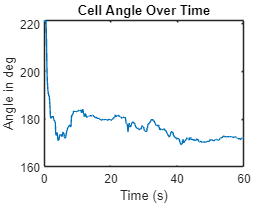


%Set Frame interval (s) and px size (micron)
Frame_int = 0.1;
px_size = 0.13;
Frame = sort(table2array(Results_0(:,"FRAME")));
Time = Frame*Frame_int;

     
% Import XM and YM values
    X_0 = table2array(Results_0(:,"POSITION_X"));
    Y_0 = table2array(Results_0(:,"POSITION_Y"));
    X_1 = table2array(Results_1(:,"POSITION_X"));
    Y_1 = table2array(Results_1(:,"POSITION_Y"));

% Compute Euclidian distance between each point. Px size already set
%(X_0, Y_0) and (X_1, Y_1) represent coordinates for each chloroplast

for i = 1:(length(X_0)-1)
    xdif_0(1,i) = X_0(i+1)-X_0(i);
    ydif_0(1,i) = Y_0(i+1)-Y_0(i);
    xdif_1(1,i) = X_1(i+1)-X_1(i);
    ydif_1(1,i) = Y_1(i+1)-Y_1(i);
   
end

%Include loop to give angle between each time point
for j = 1:length(X_0)
    ang(j) = atan2(Y_0(j)-Y_1(j),X_0(j)-X_1(j));
end
ang_deg = 180 - ang.*(180/pi);

% Angle values as variable, plot angle over time
figure()
    plot(Time, ang_deg)
    xlabel("Time (s)")
    ylabel("Angle in deg")
    title("Cell Angle Over Time")

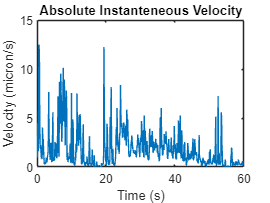



%Plot absolute velocity for all times points
vel_0 = sqrt((xdif_0.^2)+(ydif_0.^2))/Frame_int*px_size;
vel_1 = sqrt((xdif_1.^2)+(ydif_1.^2))/Frame_int*px_size;
figure()
    plot(Time(1:length(vel_0)),vel_0(1:length(vel_0)))
    xlabel("Time (s)")
    ylabel("Velocity (micron/s)")
    title("Absolute Instanteneous Velocity")

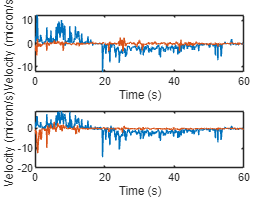



    
% Calculate velocities in x and y directions separately for each
% chloroplast
%
velx_0 = xdif_0.*(px_size/Frame_int);
vely_0 = ydif_0.*(px_size/Frame_int);
velx_1 = xdif_1.*(px_size/Frame_int);
vely_1 = ydif_1.*(px_size/Frame_int);


% Plot x and y velocities for front and rear chloroplasts in two separate
% plots
figure()
subplot(2,1,1)
plot(Time(1:length(velx_0)),velx_0(1:length(velx_0)))
hold on
plot(Time(1:length(vely_0)),vely_0(1:length(vely_0)))
hold off
xlabel("Time (s)")
ylabel("Velocity (micron/s)")

subplot(2,1,2)
plot(Time(1:length(velx_1)),velx_1(1:length(velx_1)))
hold on
plot(Time(1:length(vely_1)),vely_1(1:length(vely_1)))
hold off
xlabel("Time (s)")
ylabel("Velocity (micron/s)")


%%Calculate velocity of midpoint of two chloroplasts
vel_mid_s = []


vel_mid_s =

     []



for i = 1:length(vel_0)
    vel_mid_s(i) = ((vel_0(i)+vel_1(i))/2)*sign(velx_0(i));
end




%Compute midpoint between chloroplast for each coordinate using XM and YM values
for (j = 1:length(X_0))  

x_mid(j) = (X_0(j)+X_1(j))/2;
y_mid(j) = (Y_0(j)+Y_1(j))/2;
end
for i = 1:(length(X_0)-1)
    x_mid_dif(1,i) = x_mid(i+1)-x_mid(i);
    y_mid_dif(1,i) = y_mid(i+1)-y_mid(i);
end 
vel_mid_x = x_mid_dif.*(px_size/Frame_int);
vel_mid_y = y_mid_dif.*(px_size/Frame_int);
vel_mid = (sqrt((vel_mid_x.^2)+(vel_mid_y.^2)))';

figure()
plot(Time(1:length(vel_mid_x)),vel_mid_x)
hold on
plot(Time(1:length(vel_mid_y)),vel_mid_y)
xlabel("Time (s)")
ylabel("Velocity (micron/s)")
title("Chloroplast Midpoint Velocity")


%%Collect translation and rotation data for registration into one file
Trafo_coord = [x_mid; y_mid; ang_deg(:,1:length(x_mid))]'
csvwrite("Trafo_coord.csv",Trafo_coord)


%%Set start and end frames based on position of kymograph to be used
plt_start = 50

plt_start = 50

plt_stop = 450

plt_stop = 450

duration = plt_stop - plt_start

duration = 400


%%Create smoothed velocity graph to be displayed alongside kymograph 
plotvel = smooth(vel_mid_s,20)

plotvel =     0.6395
    1.4561
    1.7078
    3.5206
    3.9318
    3.5292
    3.1615
    2.8550
    2.7660
    2.7021


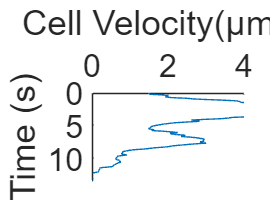

figure()
hold on
plot(plotvel(plt_start:plt_stop),Time(1:duration+1))
set(gca,"YDir","reverse","FontSize",24)
xlabel("Cell Velocity(µm/s)")
ylabel("Time (s)")
xline(0)
ax=gca;
ax.XAxisLocation = 'top';
box on
hold off